## **Driver test program to check Clothoids library**

**Test circle**

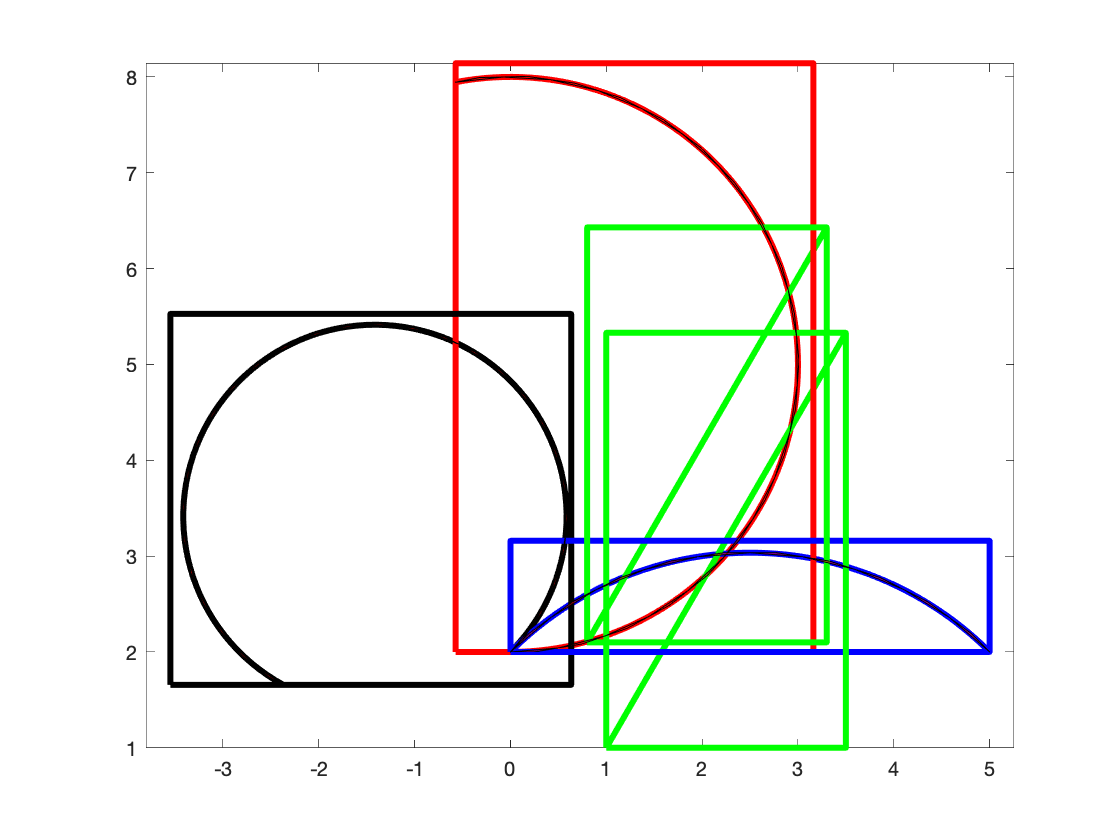

close all

% check constructors
x0     = 0;
y0     = 2;
x1     = 3;
y1     = 3;
x2     = 5;
y2     = 2;
theta0 = 0;
L      = 10;
k0     = 1/3;
L1 = CircleArc( x0, y0, theta0, k0, L );
L2 = CircleArc( x0, y0, theta0+pi/4, 1.5*k0, L );
L3 = CircleArc();
L3.build_3P(x0, y0, x1,   y1, x2, y2 );
L4 = LineSegment( x0+1,   y0-1, pi/3, 5 );
L5 = LineSegment( x0+0.8, y0+0.1, pi/3, 5 );
%
fmt1 = {'Color','red','Linewidth',3};
fmt2 = {'Color','black','Linewidth',3};
fmt3 = {'Color','blue','Linewidth',3};
fmt4 = {'Color','green','Linewidth',3};

L1.plot(100,fmt1);
hold on;
L2.plot(100,fmt2);
L3.plot(100,fmt3);
L4.plot(fmt4{:});
L5.plot(fmt4{:});

L1.plotBBox(0,fmt1{:});
L2.plotBBox(0,fmt2{:});
L3.plotBBox(0,fmt3{:});
L4.plotBBox(0,fmt4{:});
L5.plotBBox(0,fmt4{:});

L1.plotTriangles(fmt1{:});
L2.plotTriangles(fmt2{:});
L3.plotTriangles(fmt3{:});

axis equal;

%